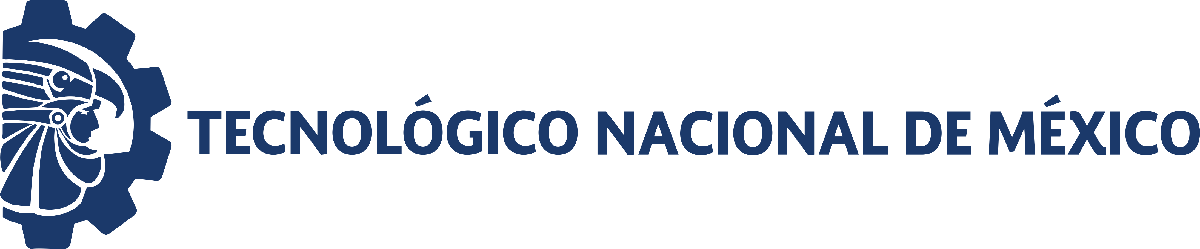                                 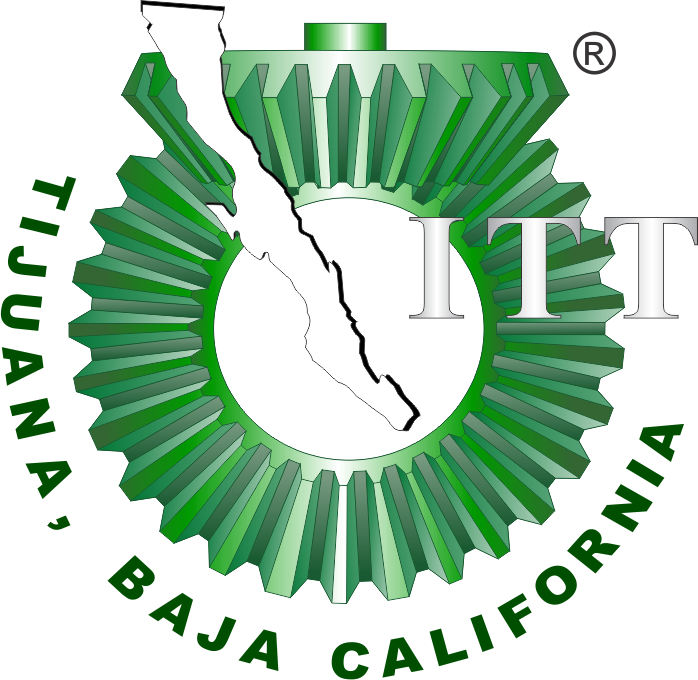

# Proyecto Final: Sistema Lacrimal

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

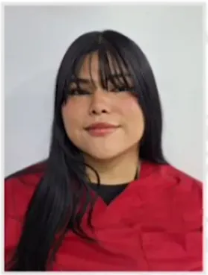

Nombre del alumno: **Paola Gonzalez Sanchez**

Número de control: **22211757**

Correo institucional: **L22211757@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

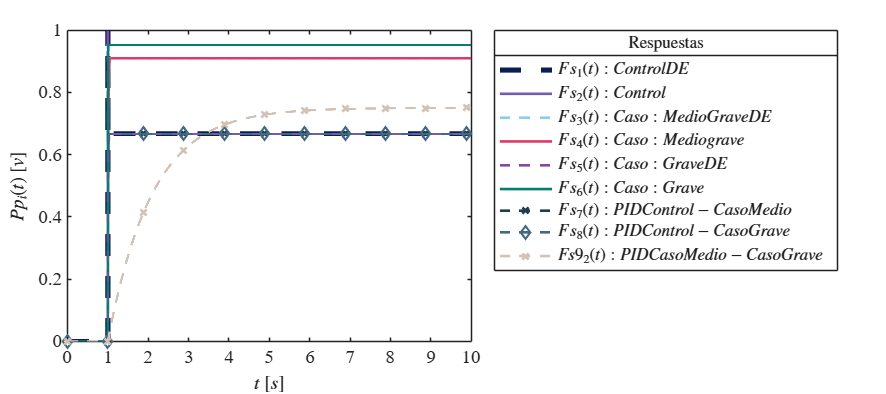

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SISTEMA';
open_system(file);
parameters.StopTime = tend; 
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

set_param('SISTEMA/Ve_in','Time','1');
set_param('SISTEMA/Ve_in','Before','0');
set_param('SISTEMA/Ve_in','After','1');
set_param('SISTEMA/Ve_in','SampleTime','0');
x = sim(file, parameters);
plotsignalss(x.t,x.Fs1, x.Fs2,x.Fs3, x.Fs4,x.Fs5, x.Fs6, x.Fs7, x.Fs8, x.Fs9);

## Caso Sano

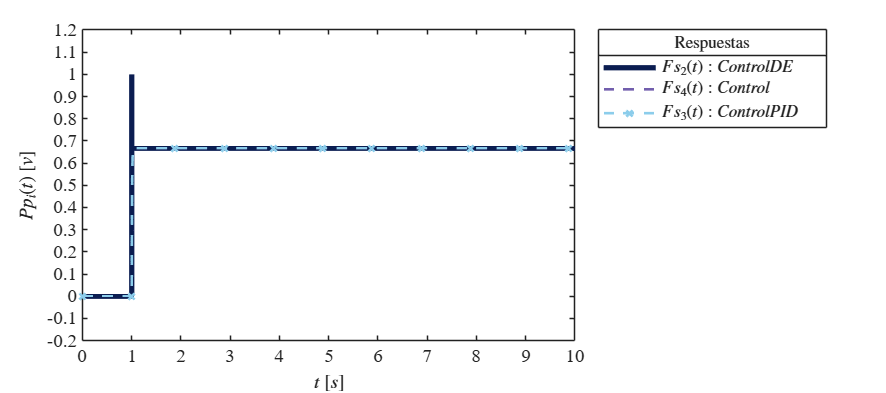

set_param('SISTEMA/Ve_in','Time','1');
set_param('SISTEMA/Ve_in','Before','0');
set_param('SISTEMA/Ve_in','After','1');
set_param('SISTEMA/Ve_in','SampleTime','0');
x = sim(file, parameters);
plotsignals1(x.t,x.Fs1, x.Fs2, x.Fs7);

## Caso Medio Grave

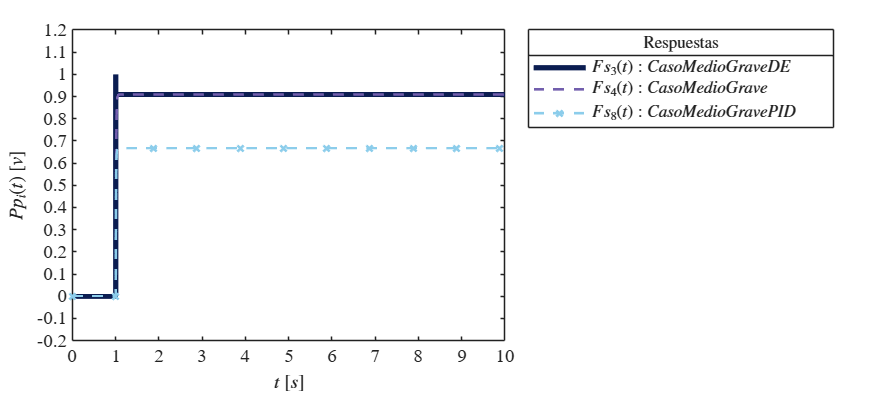

set_param('SISTEMA/Ve_in','Time','1');
set_param('SISTEMA/Ve_in','Before','0');
set_param('SISTEMA/Ve_in','After','1');
set_param('SISTEMA/Ve_in','SampleTime','0');
x = sim(file, parameters);
plotsignals2(x.t, x.Fs3, x.Fs4, x.Fs8);

## Caso Grave

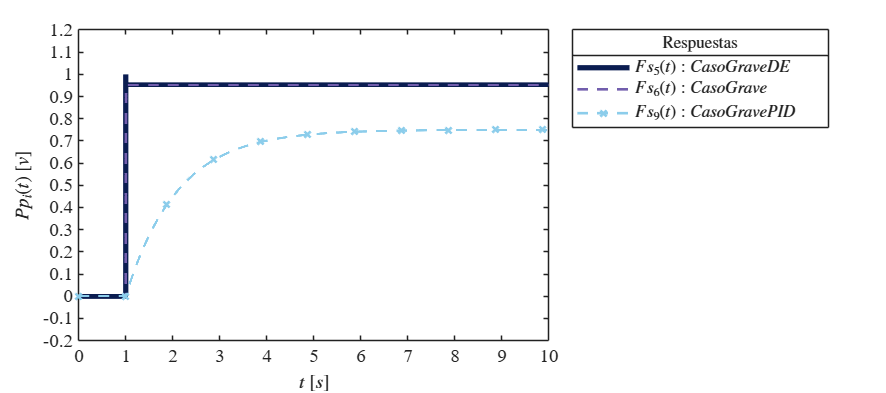

set_param('SISTEMA/Ve_in','Time','1');
set_param('SISTEMA/Ve_in','Before','0');
set_param('SISTEMA/Ve_in','After','1');
set_param('SISTEMA/Ve_in','SampleTime','0');
x = sim(file, parameters);
plotsignals3(x.t,x.Fs5, x.Fs6, x.Fs9);

## Lazo Abierto 

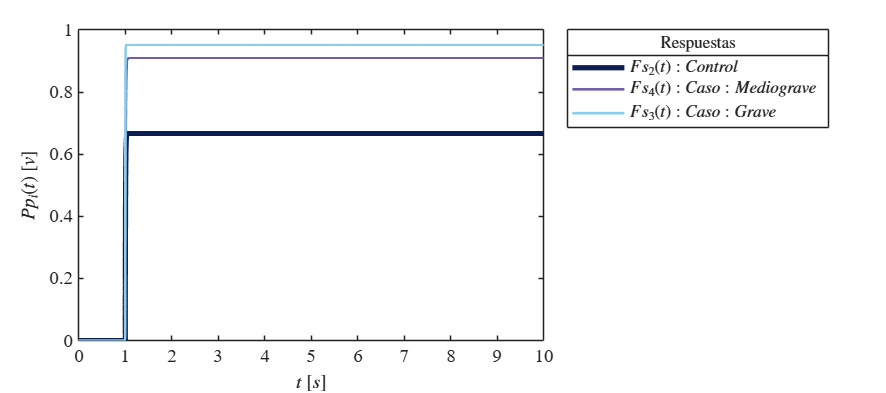

set_param('SISTEMA/Ve_in','Time','1');
set_param('SISTEMA/Ve_in','Before','0');
set_param('SISTEMA/Ve_in','After','1');
set_param('SISTEMA/Ve_in','SampleTime','0');
x = sim(file, parameters);
plotsignals(x.t, x.Fs2, x.Fs4, x.Fs6);

## Lazo Cerrado 

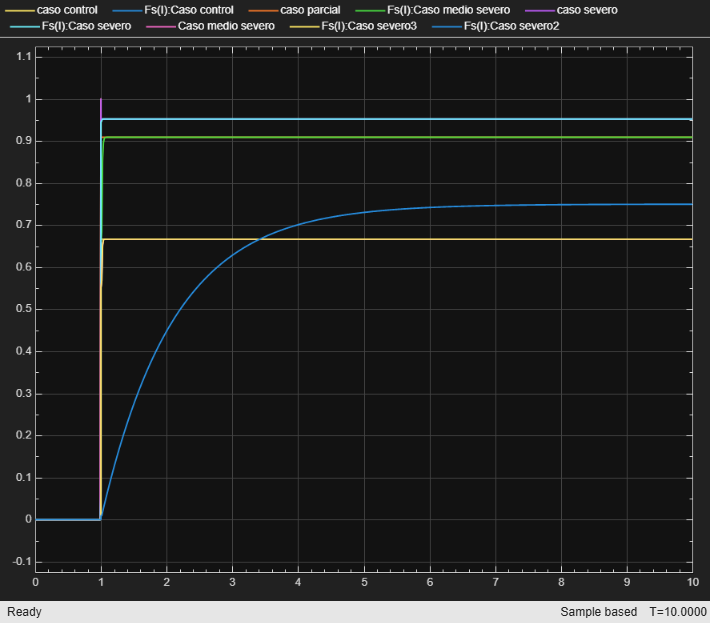

set_param('SISTEMA/Ve_in','Time','1');
set_param('SISTEMA/Ve_in','Before','0');
set_param('SISTEMA/Ve_in','After','1');
set_param('SISTEMA/Ve_in','SampleTime','0');
x = sim(file, parameters);

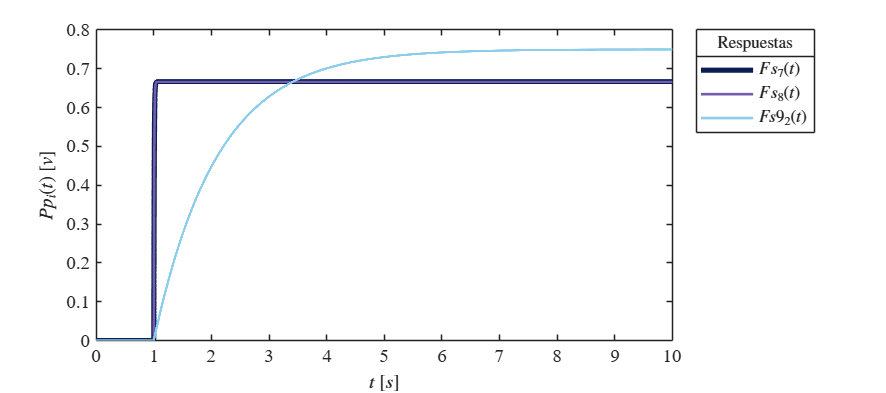

plotsignal(x.t, x.Fs7, x.Fs8, x.Fs9);

## Función: Respuesta a las señales

function plotsignalss (t,Fs1,Fs2,Fs3,Fs4,Fs5,Fs6,Fs7,Fs8,Fs9)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                27, 60, 83;
                69, 104, 130;
                210, 193, 182;
                249, 243, 239;
                ]/255;

    colororder(mycolors);
    p = plot(t, Fs1, '--', t, Fs2, '-',t, Fs3, '--',t, Fs4, '-', t, Fs5, '--',t, Fs6, '-',t, Fs7, '--x',t, Fs8, '--d', t, Fs9, '--x'...
        ,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$Fs_{1}(t): ControlDE$','$Fs_{2}(t): Control$','$Fs_{3}(t): Caso:Medio GraveDE$','$Fs_{4}(t): Caso: Medio grave$','$Fs_{5}(t): Caso: GraveDE$','$Fs_{6}(t): Caso: Grave$', '$Fs_{7}(t):PID Control-Caso Medio','$Fs_{8}(t):PID Control-Caso Grave$','$Fs9_{2}(t):PID Caso Medio-Caso Grave$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    exportgraphics(gcf, 'SistemaLacrimal.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'SistemaLacrimal.png', 'ContentType', 'vector')
end

function plotsignals (t,Fs2,Fs4,Fs6)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                27, 60, 83;
                69, 104, 130;
                210, 193, 182;
                249, 243, 239;
                ]/255;

    colororder(mycolors);
    p = plot(t, Fs2, '-', t, Fs4, '-',t, Fs6, '-' ...
        ,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$Fs_{2}(t): Control','$Fs_{4}(t): Caso: Medio grave$','$Fs_{3}(t): Caso: Grave$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    exportgraphics(gcf, 'SistemaLacrimalLA.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'SistemaLacrimalLA.png', 'ContentType', 'vector')
end

function plotsignal(t,Fs7,Fs8,Fs9)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                27, 60, 83;
                69, 104, 130;
                210, 193, 182;
                249, 243, 239;
                ]/255;

    colororder(mycolors);
    p = plot(t, Fs7, '-', t, Fs8, '-', t, Fs9, '-',...
      'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$Fs_{7}(t)$','$Fs_{8}(t)$','$Fs9_{2}(t)$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    exportgraphics(gcf, 'SistemaLacrimalLC.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'SistemalacrimalLC.png', 'ContentType', 'vector')
end
function plotsignals1 (t,Fs1,Fs2,Fs7)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                27, 60, 83;
                69, 104, 130;
                210, 193, 182;
                249, 243, 239;
                ]/255;

    colororder(mycolors);
    p = plot(t, Fs1, '-', t, Fs2, '--',t, Fs7, '--x' ...
        ,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$Fs_{2}(t): ControlDE','$Fs_{4}(t): Control$','$Fs_{3}(t): Control PID$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    ylim([-0.2, 1.2]); yticks(-0.2:0.1:2); 
    exportgraphics(gcf, 'Control.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Control.png', 'ContentType', 'vector')
end
function plotsignals2 (t,Fs3,Fs4,Fs8)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                27, 60, 83;
                69, 104, 130;
                210, 193, 182;
                249, 243, 239;
                ]/255;

    colororder(mycolors);
    p = plot(t, Fs3, '-', t, Fs4, '--',t, Fs8, '--x' ...
        ,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$Fs_{3}(t): Caso Medio GraveDE','$Fs_{4}(t): Caso Medio Grave$','$Fs_{8}(t):Caso Medio Grave PID$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    ylim([-0.2, 1.2]); yticks(-0.2:0.1:2); 
    exportgraphics(gcf, 'Caso_mediograve.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Caso_mediograve.png', 'ContentType', 'vector')
end
function plotsignals3 (t,Fs5,Fs6,Fs9)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                27, 60, 83;
                69, 104, 130;
                210, 193, 182;
                249, 243, 239;
                ]/255;

    colororder(mycolors);
    p = plot(t, Fs5, '-', t, Fs6, '--',t, Fs9, '--x' ...
        ,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$Fs_{5}(t): Caso GraveDE','$Fs_{6}(t): Caso Grave$','$Fs_{9}(t): Caso Grave PID$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    ylim([-0.2, 1.2]); yticks(-0.2:0.1:2); 
    exportgraphics(gcf, 'Caso_grave.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Caso_grave.png', 'ContentType', 'vector')
end

